# Section I - Cover Page

**Jordan Yono**

**ELEE-5920-image-processing **

**Project 0**

**Date Due - 01/31/2020**

**Date Handed In - 01/31/2020**

**Abstract**

    This project contains two parts, part 1 and part 2. I had some fun using the C++ mex and engine APIs, but time started winding down so I completed the project using standard matlab, but was able to create custom MEX functions and use the engine API successfully.  Part 1 uses the `mesh`, `surf``, `and `image` command to generate a 256x256 image with 32 even steps. Part 2 is to generate a 2D gaussian distribution which obtains its maximum of 255 in the center of the image. 

# Section II - Technical Discussion

**Part 1**

    Part 1 was very straightforward. Most of the complexity for me stemmed from lack of familiarity with Matlab. I think in future projects, I will have more detail and discussion here. The approaches for the **mesh**`,``image`, and `surf` functions were nearly identical. I'm not exactly certain of the difference between the `mesh/image` functions beyond how they default edge coloring. I created a 256x256 matrix and set the values according to the X index so that columns all had the same value. Then, I used an element wise operation to divide each value by 8 and rounding down to the floor of the step. 

**Part 2**

    Part 2 had a little more complexity, but was also relatively straightforward. The only hiccup I really had was using the `stdx` value in the example. I got some sort of `NOT FOUND` error. Instead, I replaced it with the standard deviation of 10. If this is an incorrect assumption, which I'm starting the believe to be the case, please correct me. The formula applied for a 2D gaussian distribution:


$$f\underset{\textrm{xy}}{} \left(x,y\right)*f\underset{y}{} \left(y\right)=\left(\frac{1}{\sigma \underset{x}{} \sqrt{2\pi }}e\overset{-\frac{\left(x-E\left(\left.x\right)\right)^2 \right)}{2\sigma \overset{2}{\underset{x}{}} }}{} \right)\left(\frac{1}{\sigma \underset{y}{} \sqrt{2\pi }}e\overset{-\frac{\left(y-E\left(\left.y\right)\right)^2 \right)}{2\sigma \overset{2}{\underset{y}{}} }}{} \right)$$


# Section III - Solution/Results

**Part 1**

    Similarly to Section II, I don't have too much to discuss here since the solutions are quite simple. I  created a 256x256 matrix, assigned values based on the X index. The `meshgrid` command made this quite simple. Then, I divided each element in the matrix by 8 and rounded down to the floor. The number 8 was chosen because $256\div 32=8$, so to get 32 even steps, each step set should have 8 members. The code for all three operations was virtually the same, besides some minor modifiers to normalize behavior. 

**Mesh**

% Set the colormap to gray. Default behavior is RBG spectrum.
colormap('gray')
% Create a 1x256 vector [0,1,2,... n = 255]
z = 0:255;
% Turn the vector into a 2d array 256x256 where rows are copied from the original
Z = meshgrid(z);
% Divide each element by 8 and simulate integer division by rounding to floor
Z = floor(Z/8);
% Plot
mesh(Z);

    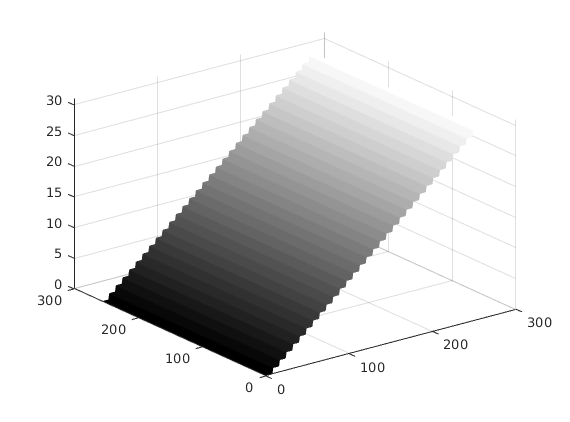

**Surf**

% Set the colormap to gray. Default behavior is RBG spectrum.
colormap('gray')
% Create a 1x256 vector [0,1,2,... n = 255]
z = 0:255;
% Turn the vector into a 2d array 256x256 where rows are copied from the original
Z = meshgrid(z);
% Divide each element by 8 and simulate integer division by rounding to floor
Z = floor(Z/8);
% Plot and set EdgeColor to none to override default behavior
surf(Z, 'EdgeColor','none');

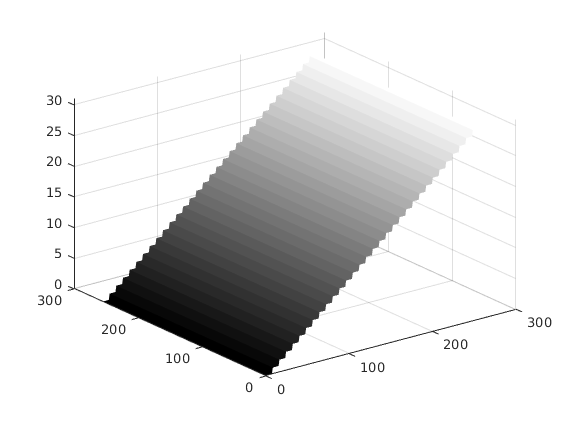

**Image**

% Set the colormap to gray. Default behavior is RBG spectrum.
colormap('gray')
% Create a 1x256 vector [0,1,2,... n = 255]
c = 0:255;
% Turn the vector into a 2d array 256x256 where rows are copied from the original
C = meshgrid(c);
% Divide each element by 8 and simulate integer division by rounding to floor
C = floor(C/8);
% Plot and override default behavior to show scaling.
imagesc(C, 'CDataMapping','scaled' )

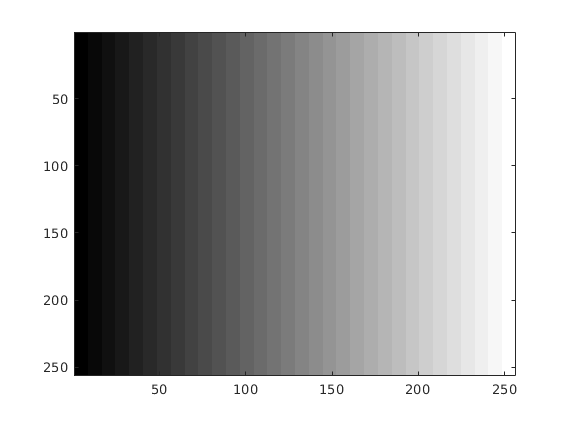

**Part 2**

    The solution here was pretty straigthforward as well and an application of the formula discussed in Section II. In the code below, you can see that I create vectors X and Y and both are 1x256. I use the `meshgrid` command to convert them into 256x256 arrays. Then, I apply the formula and scale the Z value accordingly. I am not as confident in the solution because my plot looks a little different than the example. 

% Create a 1x256 vector [0,1,2,... n = 255]
x = 0:255;
% Create a 1x256 vector [0,1,2,... n = 255]
y = 0:255;
% Turn the vectors into 2d arrays 256x256 where rows are copied from the originals
[X,Y] = meshgrid(x,y);
% Apply the formula for 2d gaussian distribution
Z = exp(-((X-127).^2+(Y-127).^2)/(2*(10.^2)));
Z = Z * 255;
% Plot
mesh(X,Y,Z)